# Pràctica 6. Exercici 3

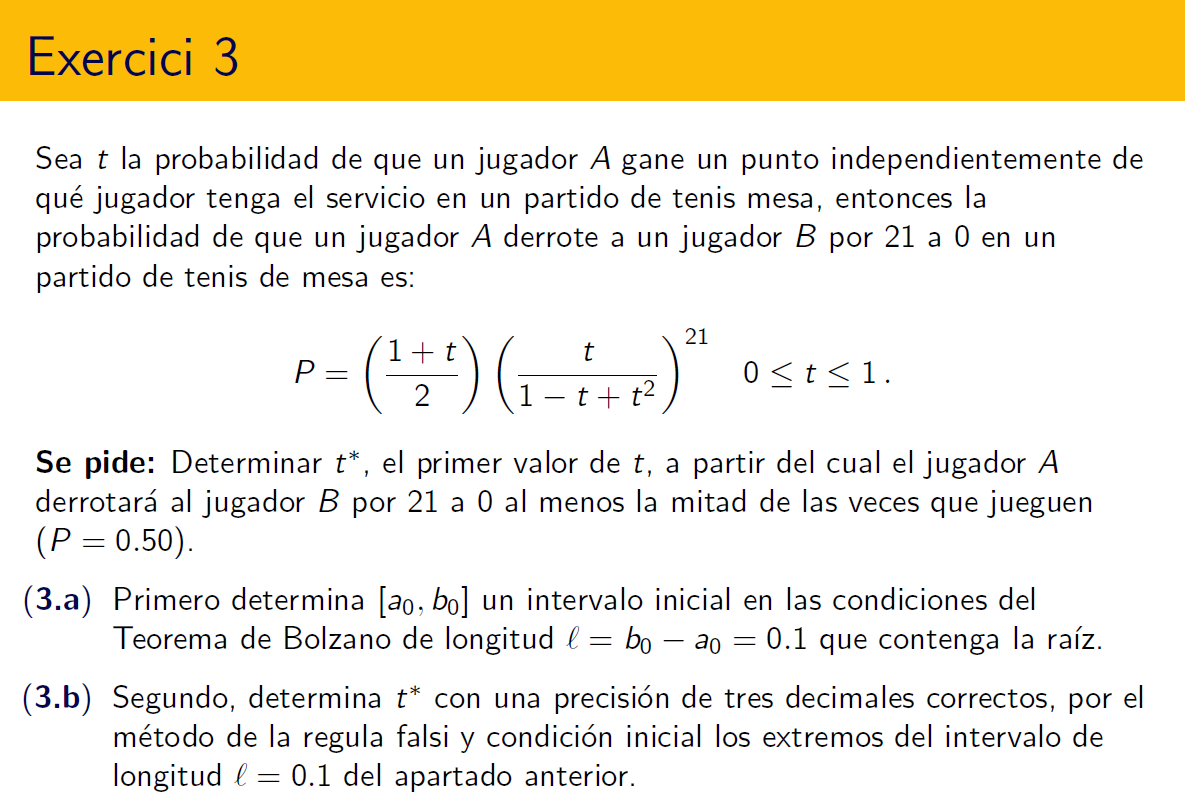

================================================================================

- `Comproveu que l'equació té una solució`

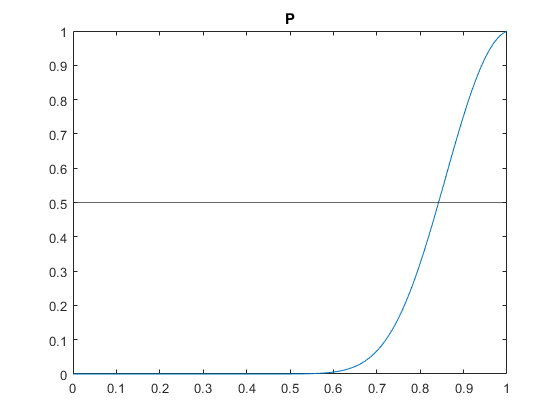

t = linspace(0,1);
P = @(x)(1+x).*(x./(1-x+x.^2)).^21/2;
plot(t,(P(t))), title('P')
yline(0.5)

f = @(x)P(x)-0.5;
zeroin(f,0,1)

    1  initial   0.000000000000000  -5.000000000000000e-01
    2  initial   1.000000000000000   5.000000000000000e-01
    3  secant    0.500000000000000  -4.998496356700892e-01
    4  secant    0.749962403264314  -3.371648009236221e-01
    5  bisect    0.874981201632157   1.463860176288266e-01
    6  secant    0.837134085425022  -2.289508244686839e-02
    7  secant    0.842252866231333  -2.309379282057211e-04
    8  secant    0.842305024415965   1.038012257703613e-06
    9  secant    0.842304791026094  -4.212924453739220e-11
   10  secant    0.842304791035566  -3.330669073875470e-16
   11  minimal   0.842304791035566   8.881784197001252e-16


ans =        0.8423


- `Determineu un interval [a_0,b_0] de longitud l=0.1 amb canvi de signe de la funció P`

t = (0:0.1:1)';
disp(array2table([t,f(t)],"VariableNames",{'t','f(t)'}))

     t       f(t)  
    ___    ________

      0        -0.5
    0.1        -0.5
    0.2        -0.5
    0.3        -0.5
    0.4        -0.5
    0.5    -0.49985
    0.6    -0.49441
    0.7    -0.43296
    0.8    -0.17695
    0.9     0.25326
      1         0.5



- `Aproximeu la solució amb tres decimals exactes pel mètode de la secant`

a = 0.8; b = 0.9; tol = 5e-4; n = 50;
xs = secant(f,a,b,tol,tol,n)

    k          x                   f                   l
        0.800000000000000  -1.769518718231426e-01                    
        0.900000000000000   2.532637444264779e-01                    
    1   0.841130973665185  -5.215915926637671e-03   0.058869026334815
    2   0.842318904242105   6.277236699459010e-05   0.001187930576920
    3   0.842304777775454  -5.897734223214712e-08   0.000014126466651


xs =        0.8423


- `Comproveu la coherència dels resultats. `

P(xs)

ans =           0.5


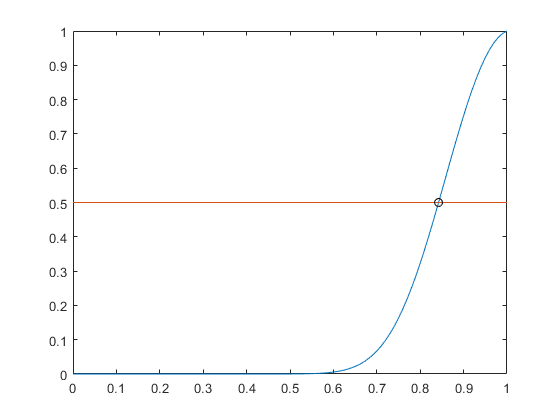

t = linspace(0,1);
plot(t,P(t),t,0.5*ones(size(t)),xs,0.5,'ko')